%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Car: Mk.11
% Subteam: Vehicle Dynamics  
% Description: Linear Bicycle Model
% Use Case: Develop the 2DoF vehicle model and gain insights on 
% steady-state and transient stability and control (eg. understeer
% and turn response)
% Current Edit Date: 08/13/2025
% Last Edited By: Tahbert Bui
% Author(s): Tahbert Bui
% References: RCVD Ch 5/6
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% 

clc; close all; clear; addpath("Functions"); addpath("tirFiles");


## Key Model Assumptions

% No lateral load transfer
% No longitudinal load transfer
% No roll or pitch
% Constant selected forward velocity (V)
% No aerodynamic effects
% Position control
% No chassis or suspension compliance effects
% The only two degrees of freedom are lateral velocity (v) 
% and yawing velocity (r).
% The input variable is steering angle (delta).


## Vehicle Parameters

res = 1000; % resolution of sim

l = 61/12; % [ft] wheelbase
CG_x = 33.7/12; % [ft] CG location along x-axis
a = CG_x; % [ft]
b = l - CG_x; % [ft]
W = 663; % [lbs] car + driver weight
g = 32.174; % [ft/sec^2]
m = W / g; % [slugs] car mass
Iz_in = 3103671.991/3.5; % [lb-in^2] Mk10 yawing moment of inertia
% mass estimate on SW is cooked, reducing by 3.5x because mass is 3.5x
% what it actually should be
% Iz_in = 5e5;
Iz = Iz_in / (g * 12 * 12); % [slug-ft^2]
k = sqrt(Iz / m); % [ft] radius of gyration in yaw
% double check Iz, seems a bit fishy
G = 4; % [deg/deg] steering ratio  

V = 60; % [ft/sec] selected forward velocity

W_F = W * a / l; % [lbs] weight on front tire
W_R = W * b / l; % [lbs] weight on rear tire

## Tire Data Initialization

% Primary Assumption: cornering stiffness at 0 slip holds for the linear
% tire region. Using static vertical loads on the front and rear axle, use
% Magic Formula data to find corresponding cornering stiffnesses.
TIRfilepath = mfeval.readTIR("magicformula_R20.tir");
lbToN = 4.44822;

Fz = [W_F; W_R] .* lbToN ./ 2; % [N] tire loads, converted from lbs
kappa = zeros(2, 1); % [deg/deg] assuming zero long slip ratio; valid for SS lat accel
alpha = zeros(2, 1); % [rad] slip angle
gamma = zeros(2, 1); % [rad] camber
phit = zeros(2, 1); % [rad] banking angle
Vx = ones(2, 1).* V .* 0.3048; % [m/sec] forward velocity, converted from ft/sec
P = ones(2, 1).*82737.1; % [Pa] tire pressure, converted from 12 psi
useMode = 111; % don't change

tirInputs = [Fz kappa alpha gamma phit Vx P]; 
tirOutputs = mfeval(TIRfilepath, tirInputs, useMode);

## Define the derivatives

[Y_beta, Y_r, Y_delta, N_beta, ...
N_r, N_delta, CF, CR] = stabilityDerivatives(V, a, b, tirOutputs);

CFDeg = deg2rad(CF);
CRDeg = deg2rad(CR);
fprintf("Front Cornering Stiffness, Linear: %.4f lb/deg\n", CFDeg);

Front Cornering Stiffness, Linear: -235.3392 lb/deg


fprintf("Rear Cornering Stiffness, Linear: %.4f lb/deg\n", CRDeg);

Rear Cornering Stiffness, Linear: -206.0991 lb/deg


fprintf("Y_beta, linear: %.4f\n", Y_beta);

Y_beta, linear: -25292.5520


fprintf("Y_r, linear: %.4f\n", Y_r);

Y_r, linear: -183.3802


fprintf("Y_delta, linear: %.4f\n", Y_delta);

Y_delta, linear: 13483.9408


fprintf("N_beta, linear: %.4f\n", N_beta);

N_beta, linear: -11002.8102


fprintf("N_r, linear: %.4f\n", N_r);

N_r, linear: -2791.0204


fprintf("N_delta, linear: %.4f\n", N_delta);

N_delta, linear: 37867.4005



% Ran then deleted velocity sweeps for these values. A lot of these 
% terms are dependent on cornering stiffnesses, which are mostly 
% independent of velocity, so it's generally safe to assume that 
% these values remain relatively the same across velocities. 
% Vertical forces is probably a different story though.

## Steady-State Solutions of Equations of Motion

delta = linspace(0, deg2rad(30), res)'; % [rad] steering angles
% steering angles need to be small to keep tires in linear range,
% otherwise the lateral forces will absolutely blow up
beta = zeros(res, 1); % [rad] body slip angle
r = zeros(res, 1); % [rad/sec] yaw velocity
for i = 1:res
    A = [Y_beta, Y_r - m*V; ...
        N_beta, N_r];
    B = [-Y_delta; -N_delta] .* delta(i);
    X = linsolve(A, B);
    beta(i) = X(1);
    r(i) = X(2);
end

v = beta .* V; % [ft/sec] lateral velocity
Y = beta .* Y_beta + r .* Y_r + delta .* Y_delta; % [lb] lateral force
N = beta .* N_beta + r .* N_r + delta .* N_delta; % [lb-ft] yawing moment
alphaF = beta + r .* (a/V) - delta; % [rad] front slip angle 
alphaR = beta - r .* (b/V); % [rad] rear slip angle
YF = alphaF .* CF; % [lb] front lateral force
YR = alphaR .* CR; % [lb] rear lateral force

deltaDeg = rad2deg(delta);
betaDeg = rad2deg(beta);
alphaFDeg = rad2deg(alphaF); 
alphaRDeg = rad2deg(alphaR); 


## Nonlinear Iteration

% To get actual values for slip angle, lateral force, and cornering
% stiffness outside of the linear region, iteration is required. Find slip
% angles from the linear solution, plug into mfeval, get lateral forces and
% cornering stiffnesses, solve for beta and r, and continue until beta and
% r change less than a set delta. Then output final result.

% tolerance = 1e-6;
% maxIters = 40;
% delta = delta;
% beta = beta;
% r = r;
% Y_beta = zeros(res, 1);
% Y_delta = zeros(res, 1);
% Y_r = zeros(res, 1);
% N_beta = zeros(res, 1);
% N_delta = zeros(res, 1);
% N_r = zeros(res, 1);
% CF = zeros(res, 1);
% CR = zeros(res, 1);
% alphaF = zeros(res, 1);
% alphaR = zeros(res, 1);
% count = 0;
% 
% for i = 1:res
%     betaStart = beta(i);
%     rStart = r(i);
%     for iter = 1:maxIters
%         alphaFLoop = betaStart + rStart * a/V - delta(i);
%         alphaRLoop = betaStart - rStart * b/V;
%         alphas = [alphaFLoop; alphaRLoop];
%         tirInputsLoop = [Fz kappa alphas gamma phit Vx P]; 
%         tirOutputsLoop = mfeval(TIRfilepath, tirInputsLoop, useMode);
%         [Y_betaLoop, Y_rLoop, Y_deltaLoop, N_betaLoop, ...
%         N_rLoop, N_deltaLoop, CFLoop, CRLoop] = stabilityDerivatives(V, a, b, tirOutputsLoop);
%         Y_beta(i) = Y_betaLoop;
%         Y_delta(i) = Y_deltaLoop;
%         Y_r(i) = Y_rLoop;
%         N_beta(i) = N_betaLoop;
%         N_delta(i) = N_deltaLoop;
%         N_r(i) = N_rLoop;
%         CF(i) = CFLoop;
%         CR(i) = CRLoop;
%         alphaF(i) = alphaFLoop;
%         alphaR(i) = alphaRLoop;
%         ALoop = [Y_betaLoop, Y_rLoop - m*V; ...
%             N_betaLoop, N_rLoop];
%         BLoop = [-Y_deltaLoop; -N_deltaLoop] .* delta(i);
%         XLoop = linsolve(ALoop, BLoop);
%         betaLoop = XLoop(1);
%         rLoop = XLoop(2);
%         betaDelta = abs(betaStart - betaLoop);
%         rDelta = abs(rStart - rLoop);
%         if (betaDelta < tolerance) && (rDelta < tolerance)
%             beta(i) = betaLoop;
%             r(i) = rLoop;
%             break
%         end
%         betaStart = betaLoop;
%         rStart = rLoop;
%         count = count + 1;
%     end
% end
% 
% v = beta .* V; % [ft/sec] lateral velocity
% Y = beta .* Y_beta + r .* Y_r + delta .* Y_delta; % [lb] lateral force
% N = beta .* N_beta + r .* N_r + delta .* N_delta; % [lb-ft] yawing moment
% alphaF = beta + r .* (a/V) - delta; % [rad] front slip angle 
% alphaR = beta - r .* (b/V); % [rad] rear slip angle
% YF = alphaF .* CF; % [lb] front lateral force
% YR = alphaR .* CR; % [lb] rear lateral force

## Control Response Characteristics

Q = N_beta.*Y_r - N_beta.*m*V - Y_beta.*N_r; 

% (1/R)/delta; curvature response to control
curveControl = (Y_beta.*N_delta - N_beta.*Y_delta) / (V.*Q); 
% r/delta; yawing velocity response to control
yawControl = V .* curveControl;
% (V^2/R)/delta; lateral acceleration response to control
latAccelControl = V .* yawControl;
% beta/delta; sideslip angle response to control
sideslipControl = (Y_delta.*N_r - N_delta.*(Y_r - m.*V)) ./ Q;

% (1/R)/Fy; curvature response to applied side force
curveSideforce = -N_beta ./ (V.*Q);
% r/Fy; yawing velocity response to applied side force
yawSideforce = V .* curveSideforce;
% (V^2/R)/Fy; lateral acceleration response to applied side force
latAccelSideforce = V .* yawSideforce;
% beta/Fy; sideslip angle response to applied side force
sideslipSideforce = N_r./Q;

% (1/R)/N; curvature response to applied yawing moment
curveYaw = Y_beta ./ (V.*Q);
% r/N; yawing velocity response to applied yawing moment
yawYaw = V .* curveYaw;
% (V^2/R)/N; lateral acceleration response to applied yawing moment
latAccelYaw = V .* yawYaw;
% beta/N; sideslip angle response to applied yawing moment
sideslipYaw = -(Y_r - m*V) ./ Q;


## Various Methods of Quantifying Understeer/Oversteer

% stability factor
K = (m.*N_beta) / (l .* (N_beta.*Y_delta - Y_beta.*N_delta));
% fprintf('Stability Factor: %.3e\n', K);

% neutral steer point
NSP = a./l - (N_beta ./ (Y_beta)) .* (1/l);

% static margin
SM = NSP - a/l;

% Bundorf cornering compliance (understeer gradient and understeer budget)
deltaD = 180/pi().*l.*K;
fprintf("Current Understeer Gradient: %.4f deg/g\n", deltaD);

Current Understeer Gradient: -0.0160 deg/g


## Significant Speeds

% tangent speed
Vt = (-g/W) .* (Y_delta.*N_r./N_delta - Y_r);

% critical/characteristic speed
if K > 0
    Vchar = sqrt(1/K);
    Vcrit = 0;
    fprintf("Characteristic Speed: %.4f ft/sec\n", Vchar);
end
if K < 0
    Vchar = 0;
    Vcrit = sqrt(-1/K);
    fprintf("Critical Speed: %.4f ft/sec\n", Vcrit);
end

Critical Speed: 134.7102 ft/sec


## Static Stability and Control

## Steering Sensitivity

% steerSens = (100 / G) * (1/(deltaD + (858*l/V^2))); % g/100 deg steering wheel

## Transient Terms

w_n = sqrt((CF.*CR.*l^2) .* (1 + K.*V^2) / (m^2.*k^2.*V^2)); % [rad/sec] car natural frequency
w_nHz = w_n / (2*pi());
dampingRatio = -(m .* (a^2.*CF + b^2.*CR) + m.*k^2.*(CF+CR)) ./ (m^2.*k^2.*V .* 2.*w_n); % [] car damping ratio
TCF = CF.*CR / m^2; % [ft^2 / sec^4] total cornering factor, higher better
g2i = l^2 ./ k^2; % [] geometry to inertia ratio, higher better

## 1DOF Analysis

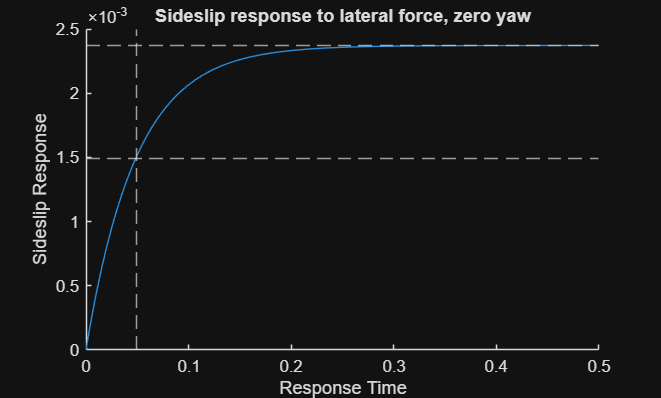

% Sideslip response to lateral force, zero yaw

timeSweep = linspace(0, 0.5, res)';
response1 = (-V./Y_beta) .* (1 - exp((Y_beta./(m.*V)) .* timeSweep));
TC1 = -m .* V ./ Y_beta;
TC_resp1 = -V ./ Y_beta .* .63;
SS1 = -V ./ Y_beta;

figure(1)
clf;
ylabel("Sideslip Response")
xlabel("Response Time")
title("Sideslip response to lateral force, zero yaw")
hold on 
plot(timeSweep, response1)
xline(TC1, '--')
yline(TC_resp1, '--')
yline(SS1, '--')
hold off

fprintf("Response Time: %.4f sec\n", TC1);

Response Time: 0.0489 sec


% Yaw response to steer angle, zero sideslip


## 2DOF Analysis

w_n2 = sqrt((N_beta / Iz) + ((Y_beta*N_r - Y_r*N_beta) / (m*V*Iz)));
w_n2Hz = w_n2 / (2*pi());
dampingRatio2 = -((N_r/Iz) + (Y_beta/(m*V))) / (2*w_n2);
w = real(w_n2 * sqrt(1 - dampingRatio2^2));
TCR = (m*V*N_delta) / (Y_delta*N_beta - Y_beta*N_delta);
TCB = (-Iz*Y_delta) / (m*V*N_delta - Y_r*N_delta + Y_delta*N_r);
WNTR = w_n2 * TCR;
WNTB = w_n2 * TCB;
% guess variables are guessed from RCVD charts, page 253, wish there was a
% better way of finding them...
rtr_guess = 3.2;
rtb_guess = 6.0;
rtr = rtr_guess / w_n2; % [sec] response time to 90% SS, yawing
rtb = rtb_guess / w_n2; % [sec] response time to 90% SS, sideslip

fprintf("Car Natural Frequency: %.4f Hz\n", w_n2Hz);

Car Natural Frequency: 2.4257 Hz


fprintf("Damping Ratio: %.4f\n", dampingRatio2)

Damping Ratio: 1.1495


fprintf("Response Time to 0.9 Steady-State, Yawing: %.4f sec\n", rtr);

Response Time to 0.9 Steady-State, Yawing: 0.2100 sec


fprintf("Response Time to 0.9 Steady-State, Sideslip: %.4f sec\n", rtb);

Response Time to 0.9 Steady-State, Sideslip: 0.3937 sec


fprintf("Total Cornering Factor: %.4e ft^2/sec^4", TCF);

Total Cornering Factor: 3.7497e+05 ft^2/sec^4

fprintf("Geometry to Inertia Ratio: %.4f", g2i);

Geometry to Inertia Ratio: 2.7821